% row vector P
Pee = [1 1]

Pee =      1     1


% column vector P
p = [1;1]

p =      1
     1


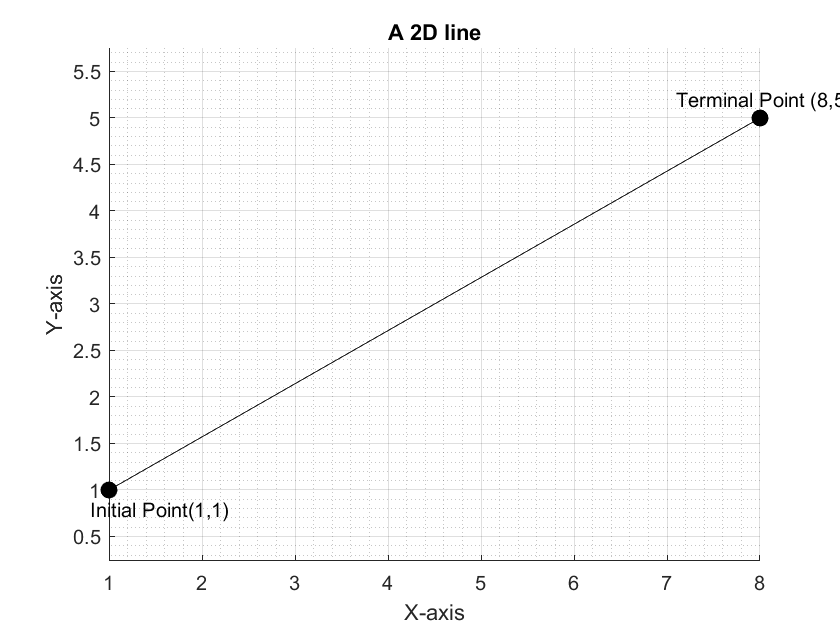

% row vector Q
Q = [8 5];
X = [1 8];
Y = [1 5];
figure
hold on
plot(X,Y,'k-')
plot(1,1,'ko','MarkerSize',8, 'MarkerFaceColor','black')
plot(8,5,'ko', 'MarkerSize', 8, 'MarkerFaceColor','black')
xlabel("X-axis"); ylabel("Y-axis"); 
grid on; grid minor;
title("A 2D line")
text(0.8,0.8,'Initial Point(1,1)',"FontSize",10);
text(7.1,5.2,'Terminal Point (8,5)',"FontSize",10);
axis equal
hold off;

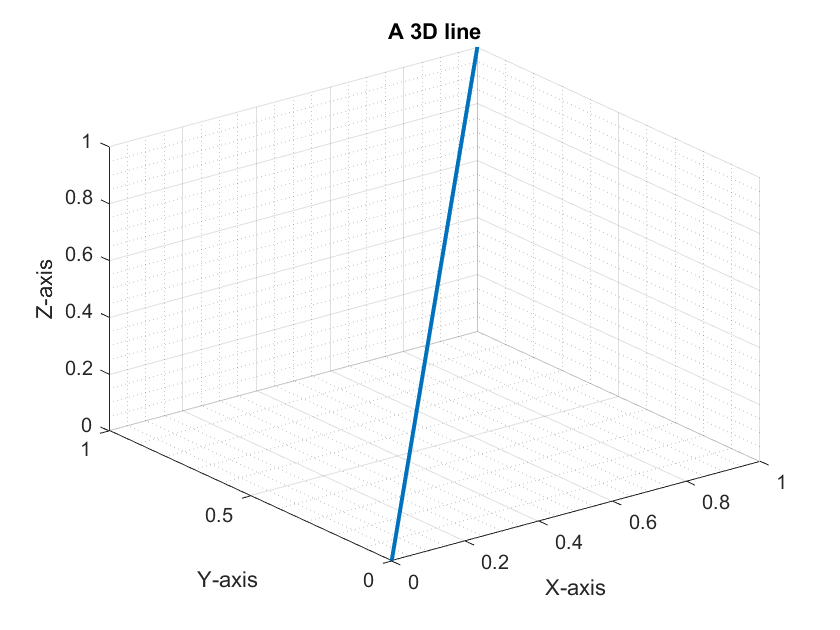


figure;
a = [0, 1];
b = [0, 1];
c = [0, 1];
plot3(a,b,c,'LineWidth',2);
title("A 3D line");
grid on; grid minor;
xlabel("X-axis"); ylabel("Y-axis"); zlabel("Z-axis");

**3D vectors, magnitude and direction**

**Use the mag() function to compute the magnitude of a 3d vector. Use direction to compute **$\alpha ,\beta ,\textrm{and}\;\gamma \;$**values of the 3D vector**

A = [-1; sym(-2/3); 0]

$$A = \left(\begin{array}{c} -1\\ -\frac{2}{3}\\ 0 \end{array}\right)$$


$$Vector \ \overrightarrow{A} = $$
 
$$\left(\overset{-1}{\underset{0}{-\frac{2}{3}}} \right)$$
  

% mag_A = mag(A)
% Norm function to calculate the magnitude of a vector
mag_A1 = norm(A)

$$mag\_A1 = \frac{\sqrt{13}}{3}$$

Calculate the direction angles

% [alpha, beta, gamma] = direction(A, mag_A)

Find the coordinates of the centre and radius of the sphere given the equation


$$x^2+y^2+z^2-2x+4y-8z=15$$


After completing the squares, we get

$(x-1)^2+(z-4)^2+(y+2)^2=36$, hence the center, C (1, -2, 4), radius, r = 6

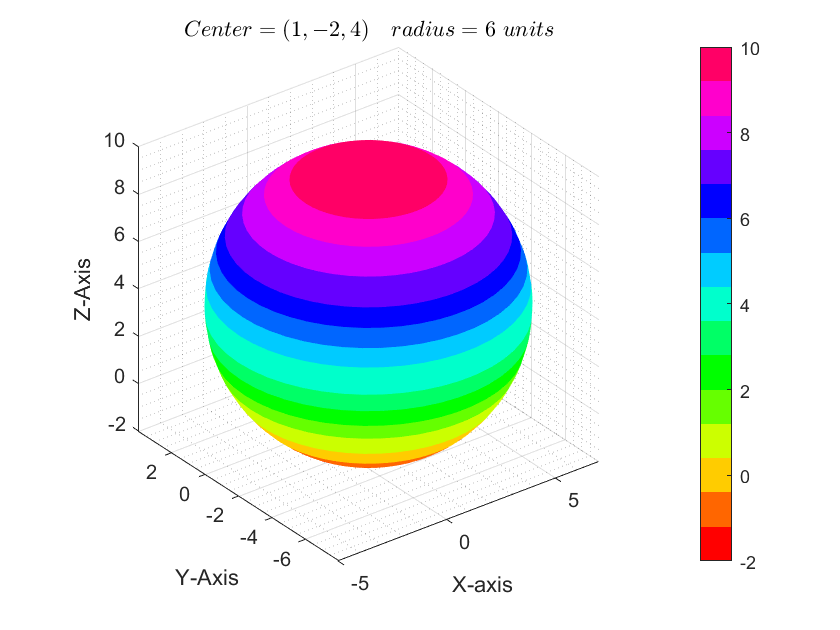

% Plots a unit sphere, with radius of 6 and center at (0,0,0)
figure;
% Returns the coordinates of the unit sphere, but does not plot
% argument spheres the number of faces as 50-by-50 faces
[X,Y,Z] = sphere(50);
% modify the colormap
colormap(summer(10));
colorbar;

radius = 6;
% Multiply the respective x,y,z coordinates by the radius(since radius = 1) 
X2 = X * radius;
Y2 = Y * radius;
Z2 = Z * radius;

% To include the x,y,z coordinates, to define the center of the 
% sphere add or subtract them respectively.
% tiledlayout(1,2)
% ax1 = nexttile;
surf(X2+1,Y2-2 ,Z2+4)
shading flat;
colormap(hsv(15))
colorbar
title('$Center = (1, -2, 4) \quad radius = 6 \ units$','Interpreter',"latex")
xlabel('X-axis'); ylabel('Y-Axis'); zlabel('Z-Axis');
grid on; grid minor;
axis equal

A 3D point

figure
x_cor1 = [2 3]

x_cor1 =      2     3


y_cor1 = [-1 2]

y_cor1 =     -1     2


z_cor1 = [4 1]

z_cor1 =      4     1


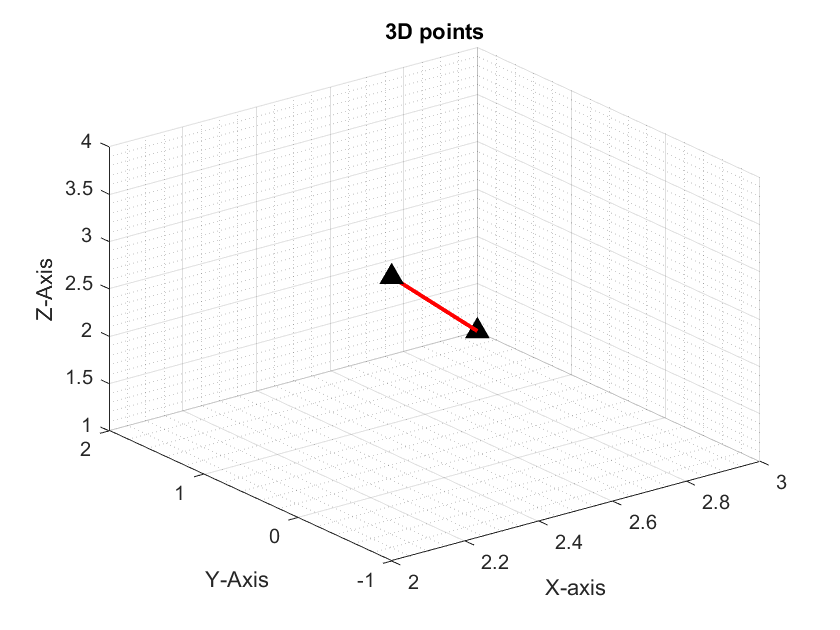

plot3(3,2,1,'k^','MarkerSize',10,'MarkerFaceColor','black')
hold on;
plot3(x_cor1,y_cor1,z_cor1, '-r', "LineWidth",2)
plot3(2,-1,4,'k^','MarkerSize',10,'MarkerFaceColor','black')
title("3D points")
xlabel("X-axis"); ylabel("Y-Axis"); zlabel("Z-Axis")
grid on; grid minor;
hold off;

A = [-1; -2; 3];
B = [2; 5; 3];

Addition of A and B

C = A + B

C =      1
     3
     6


Subtraction of A and B

D = A - B

D =     -3
    -7
     0


Dot Product of A and B

E = dot(A,B)

E = -3

norm(A)

ans = 3.7417

Transpose of a matrix

G = A'

G =     -1    -2     3


## Finding the distance between a 3D line and a point

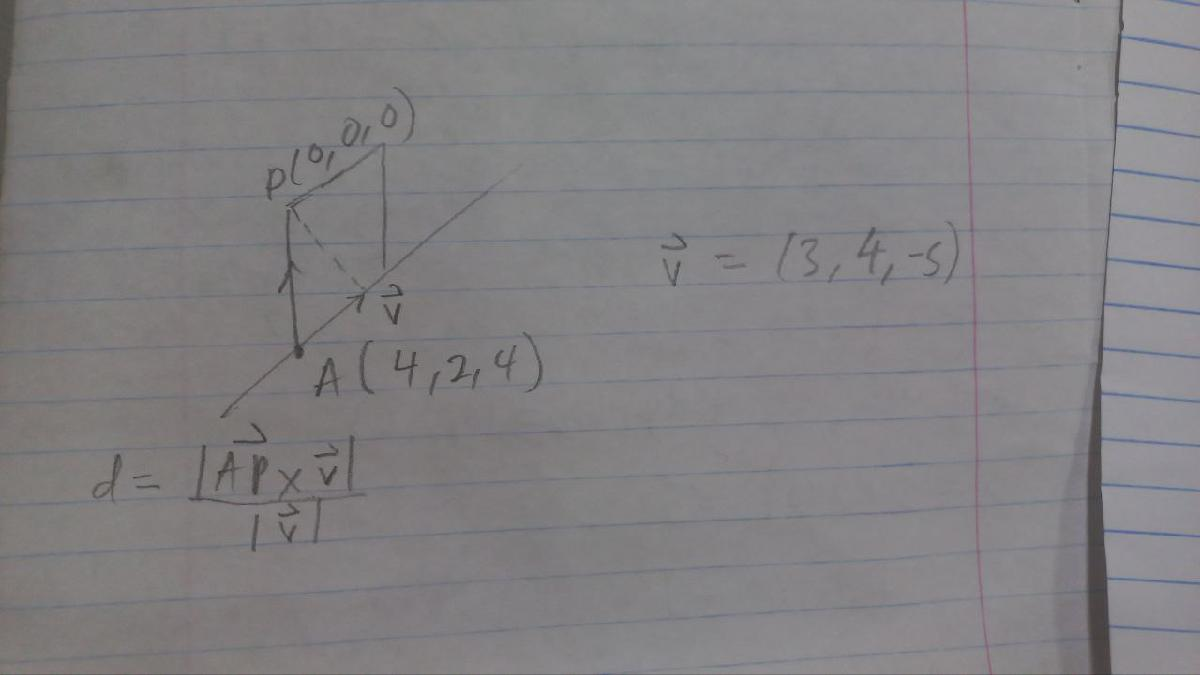

A = [4 2 4]; % A point on the line
P = [0 0 0];
v = [3 4 -5]; % the unit vector of the line

A_P = P - A;
num = norm(cross(A_P,v)) % magnitude of the cross product

num = 42.4264

dem = norm(v) % magnitude of the direction vector

dem = 7.0711

distance = num/dem % distance between the line and the point

distance = 6

## Plot a 3D plane given its equation

z = @(x,y) 2*x + 1.5*y - 4.5 

z = function_handle with value:
    @(x,y)2*x+1.5*y-4.5


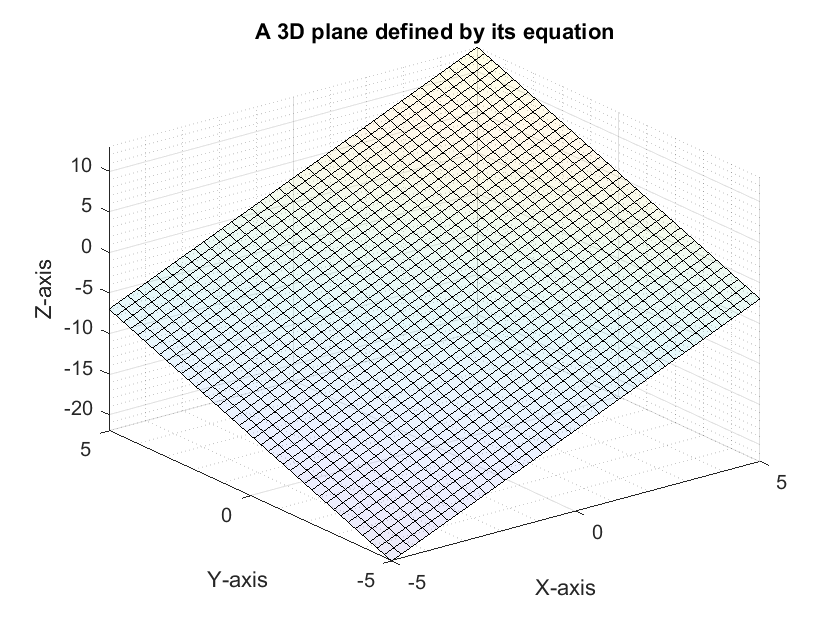

figure1 = figure;
% figure2 = figure;
axes1 = axes(figure1);
plane1 = fsurf(axes1,z);
xlabel("X-axis"); ylabel("Y-axis"); zlabel("Z-axis");
title("A 3D plane defined by its equation");
plane1.MeshDensity = 40;
plane1.FaceAlpha = 0.1; % Define opacity
grid on; grid minor;

## Plot a 3D line given its parametric equations

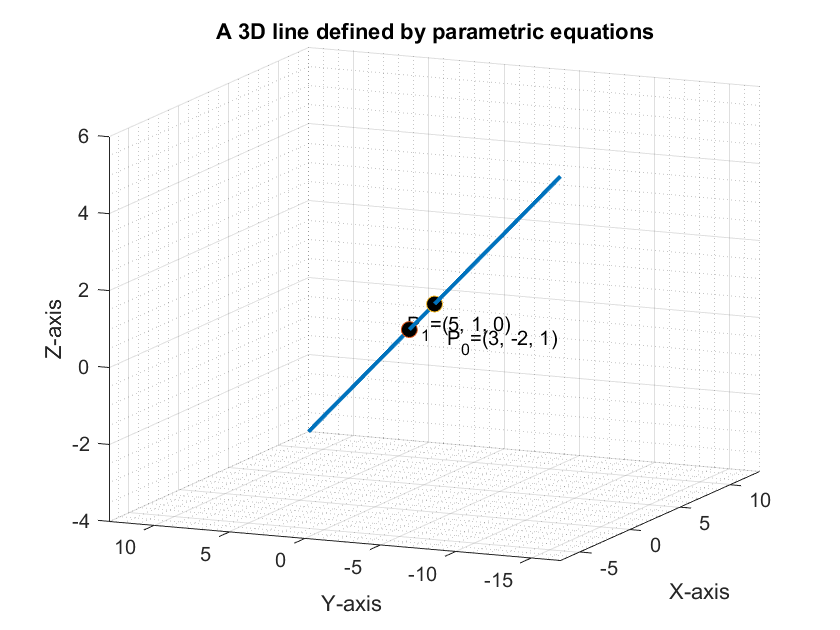

figure2 = figure;
axes2 = axes(figure2);
x = @(t) 3 + 2*t;
y = @(t) -2 + 3*t;
z = @(t) 1 - t;
fig = fplot3(axes2,x, y, z);
fig.LineWidth = 2;
hold on;
plot3(5,1,0,'o','MarkerSize',8,'MarkerFaceColor','k')
text(5.5,1.5,0,'P_1=(5, 1, 0)')
plot3(3,-2,1,'o','MarkerSize',8,'MarkerFaceColor','k')
text(3.5,-2.5,0,'P_0=(3, -2, 1)')
xlabel("X-axis"); ylabel("Y-axis"); zlabel("Z-axis");
title("A 3D line defined by parametric equations");
grid on; grid minor;

## Arc lengths

Find the arc length of the circular helix defined by$r(t) = cos(t) \hat{i} + sin(t)\hat{j} +t \hat{k}$ .(1,0,0) to the point (1,0,$2\pi$) .


$$s(t) = \int_a^b |r'(t)|dt$$
 

syms t
r(t) = [cos(t) sin(t) t]

$$r(t) = \left(\begin{array}{ccc} \cos\left(t\right) & \sin\left(t\right) & t \end{array}\right)$$

deriv = diff(r(t),t)

$$deriv = \left(\begin{array}{ccc} -\sin\left(t\right) & \cos\left(t\right) & 1 \end{array}\right)$$

squared_deriv = deriv.^2

$$squared\_deriv = \left(\begin{array}{ccc} {\sin\left(t\right)}^{2} & {\cos\left(t\right)}^{2} & 1 \end{array}\right)$$

summation = sum(squared_deriv)

$$summation = {\cos\left(t\right)}^{2}+{\sin\left(t\right)}^{2}+1$$

squared = sqrt(summation)

$$squared = \sqrt{{\cos\left(t\right)}^{2}+{\sin\left(t\right)}^{2}+1}$$

arc_len = int(squared,t,0,2*pi)

$$arc\_len = 2\,\pi \,\sqrt{2}$$

integral = vpa(arc_len,5) % This is the arc length from t = 0 to t = 2*pi

$$integral = 8.8858$$

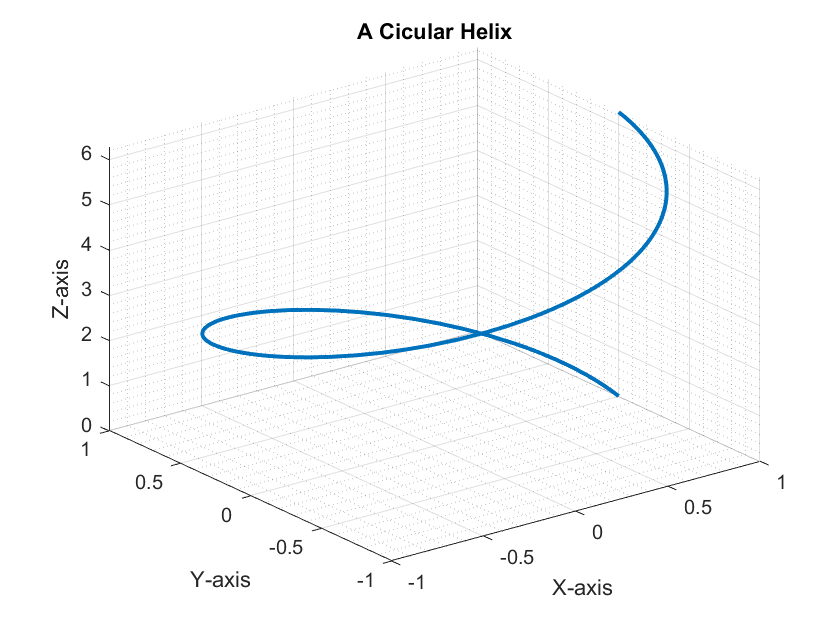


% The circular helix
figure;
xt = @(t) cos(t);
yt = @(t) sin(t);
zt = @(t) t;
fig2 = fplot3(xt,yt,zt,[0 2*pi]);
grid minor; grid on;
fig2.LineWidth = 2;
xlabel("X-axis"); ylabel("Y-axis"); zlabel("Z-axis");
title("A Cicular Helix");